Sprawozdanie nr 3

Data zajęć: 19.10.2023

Data wykonania sprawozdania: 25.10.2023

Autor: Szymon Turkiewicz

Cele laboratorium: 

-  Zaznajomienie się ze środowiskiem MATLAB

-  Ćwiczenie umiejętności: 

- tworzenia wykresów 

- automatyzacji pracy (m-skrypty) i programowania w środowisku MATLAB. 

- typy danych środowiska MATLAB

Zadanie 1

a) Utwórz m-skrypt wczytujący dane z pliku daneP.csv a następnie realizującego wizualizację danych na wykresie typu plot (każda zmienna na osobnym wykresie). Dodaj do każdego wykresu osobny tytuł.

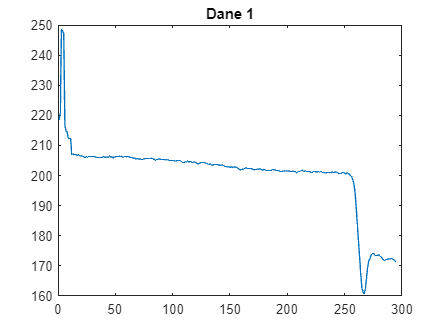

clear
dane = readtable("daneP.csv");%wczytanie danych jako tabeli
dane1 = dane{:, 1};
dane2 = dane{:, 2};
dane3 = dane{:, 3};
%rozdzielenie wczytanych danych na pojedyńcze wektory
figure
plot(dane1)
title("Dane 1")

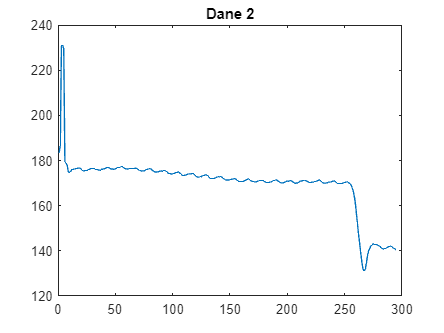

figure
plot(dane2)
title("Dane 2")

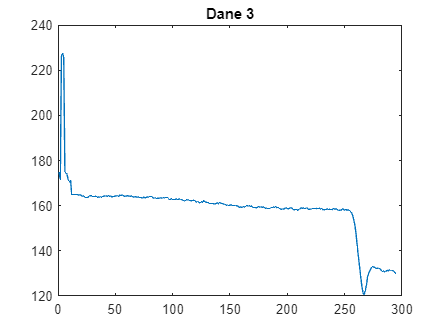

figure
plot(dane3)
title("Dane 3")

b) Z zaimportowanych danych wybierz taki fragment, na którym widoczny jest sygnał okresowy. Utwórz nową zmienną zawierającą wybrany fragment sygnału i zwizualizuj ją na osobnym oknie wykresu.

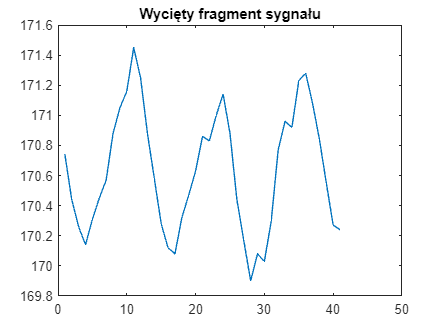

okresowe2 = dane2(180:220); % Wybierz fragment sygnału okresowe2

figure
plot(okresowe2)
title("Wycięty fragment sygnału")

c) Z wybranego fragmentu sygnału, usuń trend poprzez dopasowanie krzywej wielomianowej. Dobierz stopień wielomianu jak najmniejszego stopnia przy zachowaniu jak najmniejszego błędu dopasowania (funkcja norm). Do wykresu z poprzedniego punktu dodaj linię dopasowanego trendu (inny kolor). Utwórz nowy wykres zawierający sygnał z usuniętym trendem.

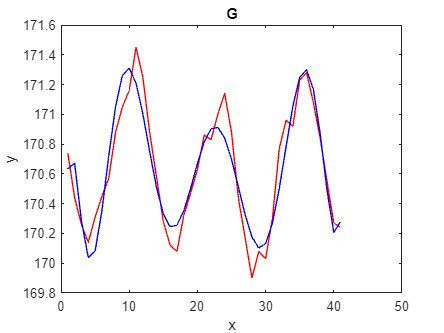

[x] = length(okresowe2);
x=1:1:x;
%wyzaczenie długości fragmentu sygnału oraz stworzenie wektora o takiej
%długości z skokiem 1
n=ones(10,1);
for i=1:1:10
    [p, ~, mu] = polyfit(x, okresowe2, i);
    y=polyval(p,x,[],mu);
    n(i)=norm(okresowe2-y);
    %ta pętla sprawdza dpoasowanie wielomianów stopni od 1 do 10 
    %do podanego fragmentu sygnału, jenak wszystkie elementy mają bardzo
    %niskie dopasowanie (n ma te same wartościn dla kazdego indexu więc
    %wyznaczony wielomian nie jest dokładnie dopasowany
end
[p, ~, mu] = polyfit(x, okresowe2,i);
y= polyval(p,x,[],mu);
hold on 
plot(x,okresowe2,"r")
title("G")
plot(x,y,'b')
xlabel("x")
ylabel("y")
hold off

d) Znajdź częstotliwość charakterystyczną sygnału. Sformatuj wykres dodając do niego w sposób programowy: opisy osi x,y i tytuł wykresu. Dodaj do wykresu punkt w miejscu maksimum (częstotliwość charakterystyczna) oraz opis informujący o wartości częstotliwości tego maksimum. 

Fs=295*2;%częstotliwość próbkowania
T=1/Fs;%okres próbkowania
L=numel(okresowe2); % długość sygnału
t=(0:L-1)*T;
y=y-y(1);
Y=fft(y);%otzrymana transformata
P2=abs(Y/L);
P1=P2(1:L/2+1);

P1(2:end-1)=2*P1(2:end-1);
f=Fs*(0:(L/2))/L

f =          0   14.3902   28.7805   43.1707   57.5610   71.9512   86.3415  100.7317  115.1220  129.5122  143.9024  158.2927  172.6829  187.0732  201.4634  215.8537  230.2439  244.6341  259.0244  273.4146  287.8049


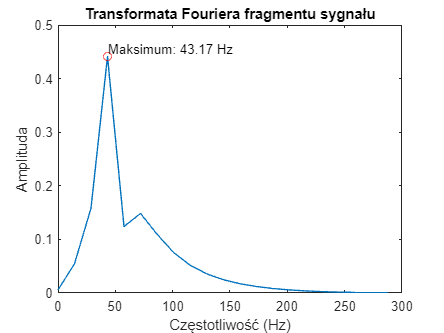

[~, idx] = max(P1); %wyznaczanie indexu dla częstotliwości maksymalnej
czestotliwosc_max = f(idx);%przypisywanie wartości częstotliwości maksymalnej
% poprzez podanie indexu do f
figure
plot(f, P1);%całość wykkresu
hold on;
plot(czestotliwosc_max, P1(idx), 'ro');%zaznaczenie punktu maksymalnego
text(czestotliwosc_max, P1(idx), sprintf('Maksimum: %.2f Hz', czestotliwosc_max), 'VerticalAlignment', 'bottom');
xlabel('Częstotliwość (Hz)');
ylabel('Amplituda');
title('Transformata Fouriera fragmentu sygnału');
xlim([0 300])%dostosowanie osi wykresu do otrzymanych danych
ylim([0 0.5])

Zadnie 2

a) Przy pomocy polecenia randn wygeneruj tablicę 3x3 liczb pseudolosowych R o rozkładzie normalnym (średnia 0 i odchylenie standardowe). Następnie utwórz zmienną A jako typ UINT32, zawierającą liczbę 100. Pomnóż zmienną R przez A, odpowiednio dostosowując typy danych. Rezultat (zmienna B) powinna być typu UINT32. Zwróć uwagę czy rezultaty mnożenia są poprawne ! W sprawozdaniu zanotuj liczbę bajtów potrzebną do zapamiętania jednej liczby typu double oraz jednej liczby typu UINT32

R =randn(3,3);
A=uint32(100);
R=uint32(R);
%przy przekształceniu macierzy na macierz typu uint32 elementy 
%tej maicerzy przestają być floatami a wartości ujemne zamieniają się w 0
%powoduje to że wyniki mnożenia nie są poprawne mimo tego, że mnożenie 
%zachodzi poprwanie, a otrzymany wynik jest mnożeniem otrzymanej po
%przekształceniu macierzy oraz skalara A
B=A*R;

b) Utwórz dwie tablice znakowe zawierające teksty: „ćwiczenie 2” oraz „laboratorium 1”. Połącz te dwie tablice tak aby tablica wynikowa zawierała tekst jak poniżej

str1='ćwiczenie 2';
str2='laboratorium 1';
str3=strvcat(str1,str2)

str3 = 2×14 char array
    'ćwiczenie 2   '
    'laboratorium 1'


%funkcja ta łączy stringi, każdemu osobnemu stringowi przypisuje osobną
%linijkę

c) Utwórz tablicę znakową str1 zawierającą tekst „Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud”. Znajdź indeksy słów zaczynających się na literę „b”, kończących na literę „d” i nie zawierających litery „u”.

str1="Krasnoludy przeszły przez rzekę w bród," + ...
    " nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud"

str1 = "Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud"

str_list=strsplit(str1, ' ')% rozbicie tekstu na liste zawierającą poszczególne słowa

str_list = 1×18 string array
    "Krasnoludy"    "przeszły"    "przez"    "rzekę"    "w"    "bród,"    "nie"    "zamoczywszy"    "swych"    "bród"    "i"    "do"    "tego"    "zmywszy"    "ze"    "swych"    "nóg"    "brud"


wyrazenie_regexp = 'b[^u]*d';%wyrażenie które zostanie użyte jako argument funkcji regexp
indeksy=[];
for i=1:numel(str_list)
    if ~isempty(regexp(str_list{i}, wyrazenie_regexp,'once','ignorecase'))
        %funkcja sprawdza czy dane słowa spełniają nałożone ograniczenia
        indeksy= [indeksy,i];
        %jeżeli tak zapisuje ich indeksy w liscie słów
    end
end
indeksy

indeksy =      6    10


d) Utwórz tablicę komórkową o rozmiarze 2x2 zawierającą następujące dane jak na rysunku poniżej. Wybierz z tablicy komórkowej, tablicę liczb pseudolosowych znajdującą się w komórce 2-wiersz, 1- kolumna, dodaj do niej wartość 100, a rezultat zapisz w to samo miejsce do tablicy komórkowej.

tablica= cell(2,2);
tablica{1,1}=123;
tablica{1,2}='abcd';
tablica{2,1} = randi(3,3);%prawdopodobnie najbardziej optymalne było by użycie randn ale 
%macierz nie wyglądała by estetycznie w tabeli
tablica{2,2} = 0.1;
tablica{2,1}= tablica{2,1}*100

tablica = 2×2 cell array
    {[     123]}    {'abcd'  }
    {3×3 double}    {[0.1000]}


e) Oblicz całkę oznaczoną w przedziale 𝑥 ∈ (−2,2) z funkcji 𝑓(𝑥) = 𝑥 2 − 2 ∙ 𝑥 + 4 i narysuj jej wykres dla tego przedziału.

fun = @(x) x.^2 -2*x+4;
q=integral(fun,-2,2)

q = 21.3333

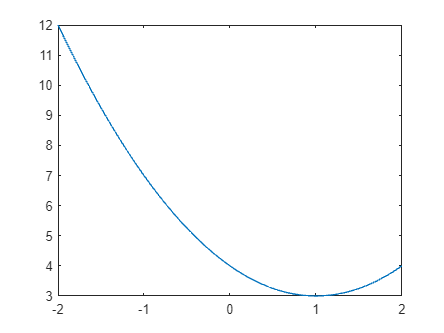

figure 
fplot(fun, [-2,2])%wykres funkcji

y=zeros(41,1);
x=-2:0.1:2;

for i = 1:1:41
    y(i)=integral(fun,-2,x(i));
end
y

y =          0
    1.1703
    2.2827
    3.3390
    4.3413
    5.2917
    6.1920
    7.0443
    7.8507
    8.6130


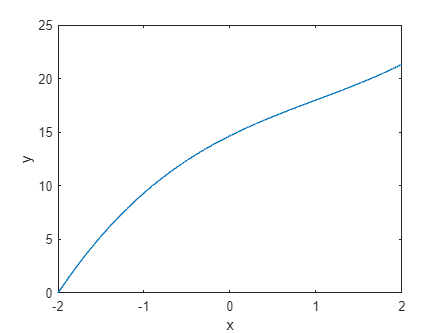

figure
plot(x,y)%wykres całki
xlabel("x")
ylabel("y")

f) Utwórz typ danych tabelaryczny (table) zawierający dane jak na rysunku poniżej. Wyeksportuj dane z tabeli do pliku CSV.

imiona={'Rafał','Monika','Paweł','Elżbieta','Mirek'};
imiona = string(imiona);
matematyka = randi([30, 100], 1, 5);
fizyka = randi([0, 100], 1, 5);
chemia = randi([0, 100], 1, 5);
T=table(imiona',matematyka',fizyka',chemia','VariableNames',{'Imiona','Matematyka','Fizyka','Chemia'});
%aby ustawienie odpowiednich elementów było pionowe, a nie poziome należy
%wszystkie  listy użyć w funkcji jako transpozycje tych list
writetable(T, 'Tabela.csv', 'Delimiter', ',');
disp(T)

      Imiona      Matematyka    Fizyka    Chemia
    __________    __________    ______    ______

    "Rafał"           37          43        11  
    "Monika"          85          70        94  
    "Paweł"           50          76        18  
    "Elżbieta"        72          43        26  
    "Mirek"           98          66        80  



Wnioski:

- Matlab zawiera wiele funkcji matematycznych, które znacznie ułatwiają wykonywanie wielu obliczeń oraz reprezentację danych. Funkcje, takie jak *fft, integral, polyfit, polyval, norm, table,* działają również na wektorach, o ile wketory przekazywane są jako argumenty w odpowiedniej formie.

- Oprogramowanie to pozwala także na zapisywanie danych w formie tabeli do osobnych plików za pomocą funkcji *writetable*. Warto również zwrócić uwagę, że wczytywanie danych z pliku jest możliwe, ale należy pamiętać o odpowiedniej komendzie w zależności od rodzaju pliku i danych, jakie ten plik zawiera. Można także skorzystać z wbudowanej właściwości Matlaba, znanej jako import wizard, która może napisać funkcję do wczytywania zaznaczonych przez nas danych.

- Matlab posiada również funkcje służące do interpretowania tekstu jako dane, a także operowania na tak stworzonych danych np. *regexp, strsplit*

- FFT czy Fast Fourier Transform to funkcja pozwalająca na dokonanie transformaty Fouriera na danych otrzymanych jako argument, polega to w rozłożeniu sygnałyu na składowe co pozwala określić, które częstotliwości są dominujące w tym sygnale